# MATLAB图像处理相关函数

## 调整图像大小

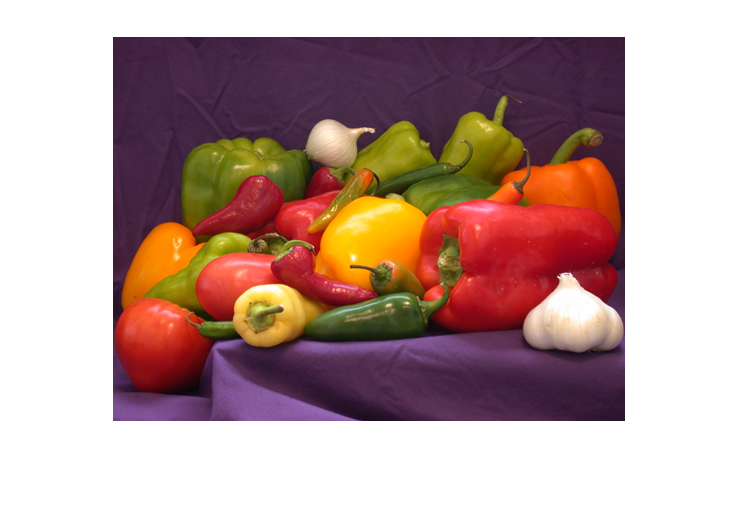

I = imread('peppers.png');
imshow(I)

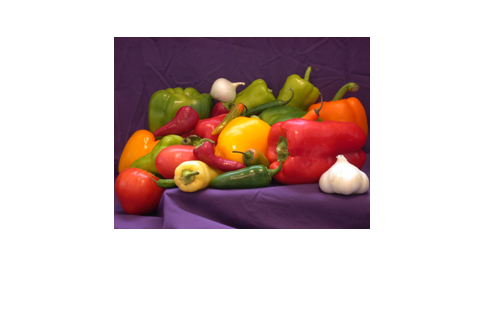

J = imresize(I, 0.5);
imshow(J)

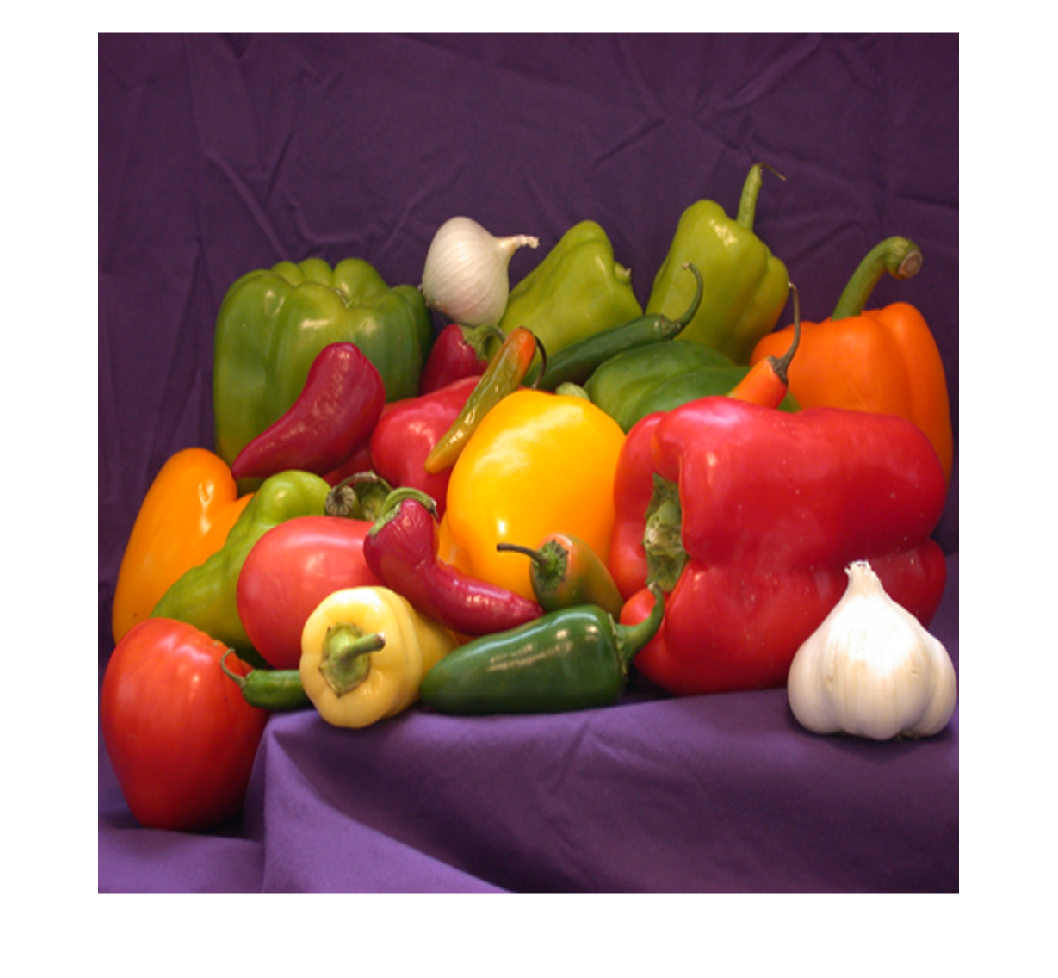

K = imresize(I, [1000, 1000]);

## 旋转图像

J2 = imrotate(I, 30)

J2 = 589×636×3 uint8 数组
J2(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

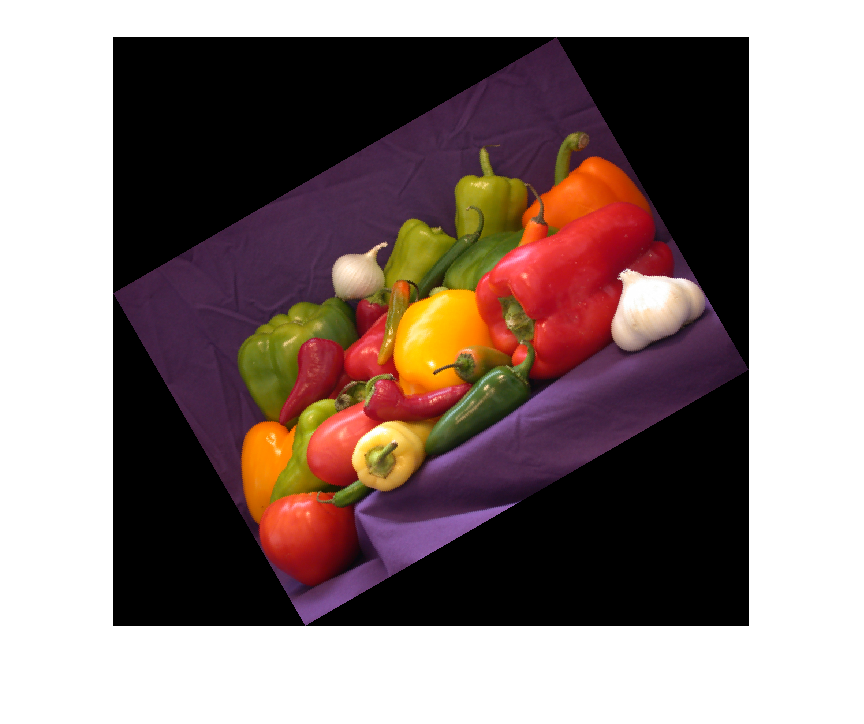

imshow(J2)

## 图像的加减乘除

J3 = imadd(I, 50)

J3 = 384×512×3 uint8 数组
J3(:,:,1) =

   112   113   113   115   116   113   111   113   113   114   114   111   115   114   111   112   113   115   115   114   111   114   115   114   116   121   117   115   114   112   118   118   120   120   121   120   118   124   124   120   120   121   121   122   124   120   119   120   117   117   117   119   119   116   117   117   121   120   119   117   118   121   119   120   121   121   121   120   117   118   117   110   107   106   101    96    95   101   104   104   105   108   104   104   107   108   110   110   108   109   107   110   113   117   120   119   120   120   119   121   120   117   118   119   116   117   118   116   117   114   113   115   116   116   115   112   112   116   116   114   113   114   112   115   117   111   114   114   115   115   112   111   115   118   117   115   120   120   115   116   118   118   117   120   120   122   120   120   120   118   120   121   121   121   118   121   123   121   119   120   

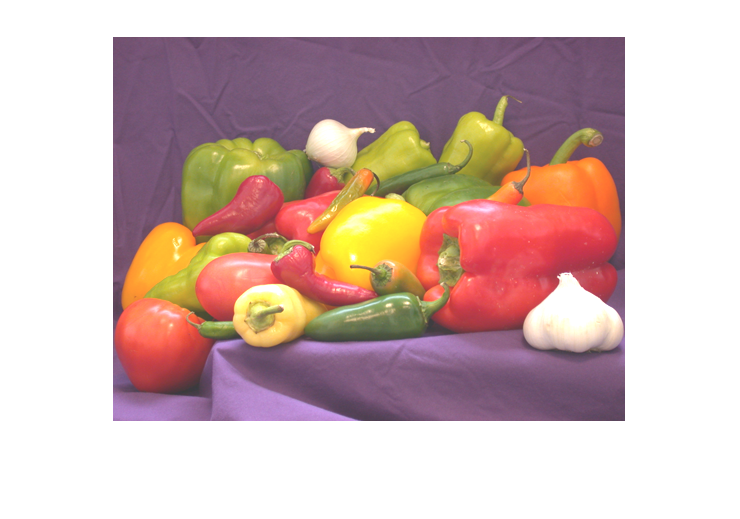

imshow(J3)

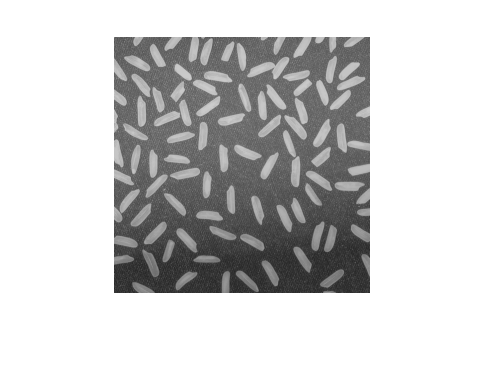

I2 = imread('rice.png');
imshow(I2)

I3 = imread('cameraman.tif')

I3 = 256×256 uint8 矩阵
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156   159   158   160   157   165   159   161   158   162   162   161   163   159   162   164   163   164   165   169   164   163   165   161   163   165   168   167   165   164   163   169   169   169   170   170   169   170   170
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156   

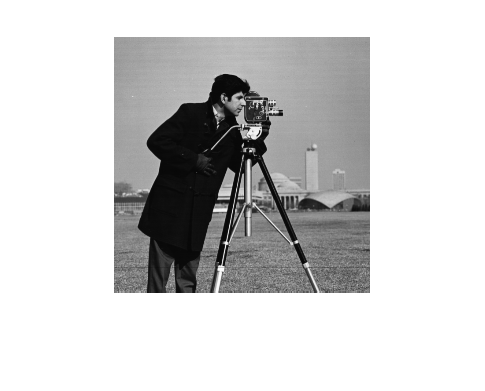

imshow(I3)

I4 = imadd(I2, I3)

I4 = 256×256 uint8 矩阵
   255   251   253   254   255   255   248   248   252   255   249   255   241   247   253   252   255   250   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   253   255   240   255   248   249   245   244   254   242   254   251   255   255   250   255   249   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   253   255   255   241   255   248   252   254   253   251   255   255   255   255   249   254   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   251   255   255   255   255   255   253   255   255   255   255
   255   254   255   245   254   248   255   253   251   243   244   255   

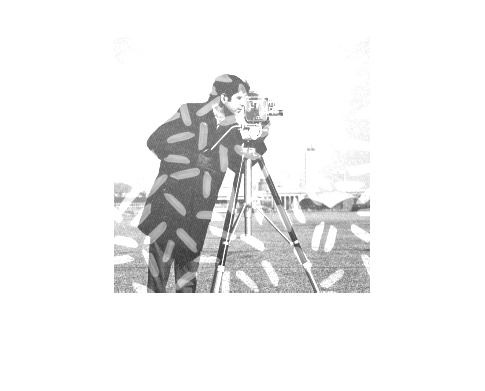

imshow(I4)

I5 = imsubtract(I3, I2)

I5 = 256×256 uint8 矩阵
   34   67   63   56   56   49   70   68   62   48   67   63   79   73   67   64   57   72   36   56   42    0    0    0    0    0    0    0    0   35   56   55   65   59   47   74   50   67   62   65   71   55   74   64   70   77   78   67   60   74
   61   55   55   76   57   70   67   71   72   66   68   58   67   47   63   64   66   69   59   58    4    0    0    0    0    0    0    0    8   61   62   62   61   62   51   68   61   75   66   70   70   61   69   77   79   82   76   57   75   75
   59   52   55   69   60   64   66   62   61   65   58   38   64   57   71   62   57   67   61   44    0    0    0    0    0    0    0    0   60   58   63   65   74   58   59   67   60   70   64   79   65   67   77   54   70   81   76   72   83   58
   58   54   58   71   60   70   48   63   65   77   66   53   53   66   64   47   70   50   61   16    0    0    0    0    0    0    0   35   70   53   58   60   63   64   67   58   64   74   69   70   52   77   68   75   69

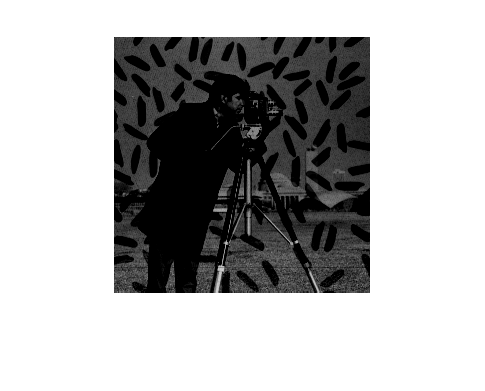

imshow(I5)

I6 = immultiply(I2, 1.5)

I6 = 256×256 uint8 矩阵
   183   138   143   149   153   161   134   135   143   165   137   144   122   131   140   141   159   134   189   156   183   255   255   255   255   255   255   255   255   191   158   165   150   158   179   137   171   149   158   150   141   164   144   153   146   135   138   152   164   138
   149   149   153   123   150   134   137   131   129   141   131   147   138   167   146   140   149   135   153   150   237   255   255   255   255   255   255   255   234   156   161   153   153   155   165   143   156   140   152   143   141   153   150   138   135   132   141   168   143   143
   146   161   155   129   147   138   140   144   144   140   150   182   144   155   134   144   159   141   152   174   255   255   255   255   255   255   255   255   158   156   147   150   137   159   161   147   156   144   155   129   150   146   140   168   146   129   141   144   129   162
   153   150   149   131   146   134   165   143   140   125   134   155   

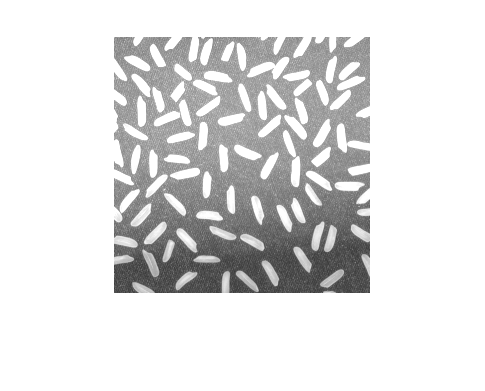

imshow(I6)

## 直方图和直方图均值化

p1 = imread("tire.tif")

p1 = 205×232 uint8 矩阵
    6   14   10   10    4    3    2    2    1    1    3    4    3    2    2    1    1    0    2    3    2    6    5    2    4    1    1    1    4    3    1    3    2    2    1    0    1    1    4    4    0    1    1    1    2    1    1    1    1    1
   11   16   17   20    6    3    4    4    2    3    5   10    7    1    2    2    1    2    1    1    1    5    5    3    4    2    2    2    3    2    2    3    2    2    1    2    3    2    6    7    1    1    2    3    2    2    2    1    2    4
   11   20   15   10    5    4    4    3    6    7    7    5    2    1    1    2    3    3    2    2    4    0    2    3    2    4    5    4    3    2    3    1    1    2    2    2    3    2    2    2    2    2    2    2    2    2    2    2    1    6
   13   16    6    2    2    2    2    9   11    7    1    1    2    2    4    4    2    2    3    4    3    2    5    2    2    1    6   10    2    2    3    3    1    1    2    1    2    1    3    2    1    1    1    1    2

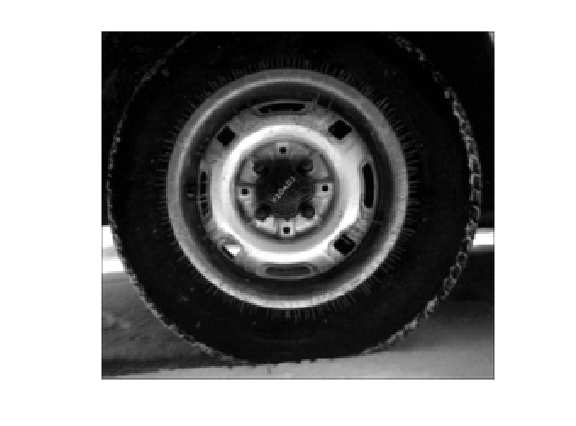

imshow(p1)

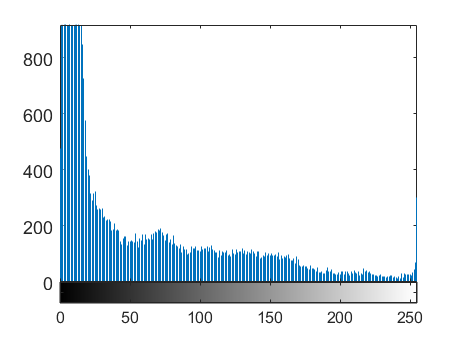

imhist(p1)

p2 = histeq(p1)

p2 = 205×232 uint8 矩阵
    49   101    73    73    36    28    16    16     4     4    28    36    28    16    16     4     4     0    16    28    16    49    40    16    36     4     4     4    36    28     4    28    16    16     4     0     4     4    36    36     0     4     4     4    16     4     4     4     4     4
    81   113   117   125    49    28    36    36    16    28    40    73    53     4    16    16     4    16     4     4     4    40    40    28    36    16    16    16    28    16    16    28    16    16     4    16    28    16    49    53     4     4    16    28    16    16    16     4    16    36
    81   125   109    73    40    36    36    28    49    53    53    40    16     4     4    16    28    28    16    16    36     0    16    28    16    36    40    36    28    16    28     4     4    16    16    16    28    16    16    16    16    16    16    16    16    16    16    16     4    49
    93   113    49    16    16    16    16    65    81    53     4     4   

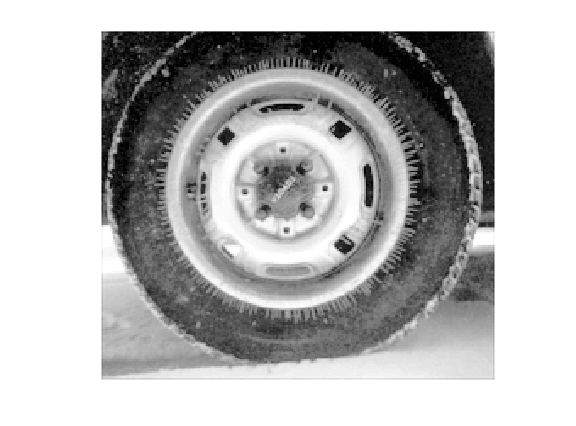

imshow(p2)

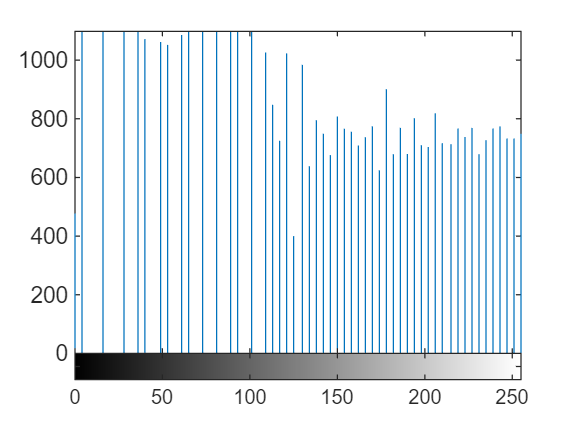

imhist(p2)

## 标注连通分量

coin = imread('coins.png')

coin = 246×300 uint8 矩阵
   49   50   48   49   48   48   49   50   50   50   50   49   49   48   50   50   51   50   49   49   48   50   52   50   50   49   50   51   50   49   50   49   49   51   51   50   51   51   52   51   51   51   51   50   52   52   51   52   52   53
   47   47   49   48   50   49   50   48   49   49   49   49   48   48   49   48   49   50   50   50   49   49   49   49   50   49   49   50   50   51   51   52   50   52   50   50   50   51   52   50   51   52   52   52   51   50   50   50   50   50
   48   48   49   49   49   49   49   49   49   50   49   50   50   50   49   49   49   49   50   49   48   48   50   50   50   51   50   50   51   51   51   50   49   50   50   50   50   49   51   51   50   51   52   53   52   52   53   51   51   52
   48   50   49   48   48   50   49   50   50   48   50   49   50   50   49   50   49   50   49   50   50   48   50   52   50   49   50   51   50   50   51   49   49   49   50   50   50   49   51   51   50   52   52   53   

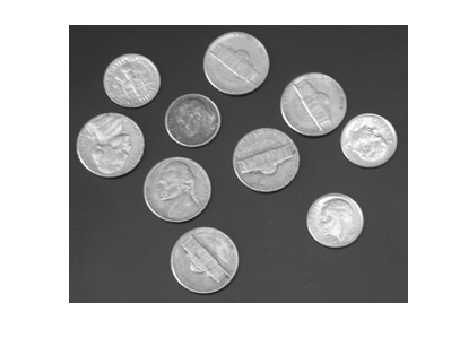

imshow(coin)

c = imbinarize(coin)

c = 246×300 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

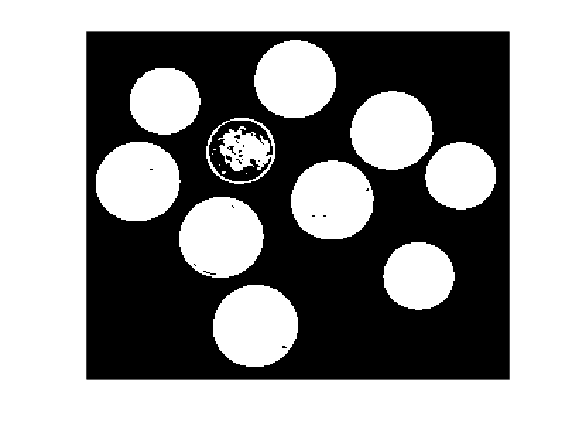

imshow(c)

c2 = imsubtract(coin, imopen(coin, strel('disk', 50)))  %开运算，先腐蚀后膨胀

c2 = 246×300 uint8 矩阵
   2   3   1   2   1   1   2   3   3   2   2   1   1   0   2   2   3   2   1   1   0   2   4   2   2   1   2   3   2   1   2   1   1   2   2   1   2   2   3   2   2   2   2   1   3   3   2   3   3   4
   0   0   2   1   3   2   3   1   2   1   1   1   0   0   1   0   1   2   2   2   1   1   1   1   2   1   1   2   2   3   3   4   2   3   1   1   1   2   3   1   2   3   3   3   2   1   1   1   1   1
   1   1   2   2   2   2   2   2   2   2   1   2   2   2   1   1   1   1   2   1   0   0   2   2   2   3   2   2   3   3   3   2   1   1   1   1   1   0   2   2   1   2   3   4   3   3   4   2   2   3
   1   3   2   1   1   3   2   3   3   0   2   1   2   2   1   2   1   2   1   2   2   0   2   4   2   1   2   3   2   2   3   1   1   0   1   1   1   0   2   2   1   3   3   4   2   4   4   3   3   2
   1   1   0   1   3   2   2   3   2   0   1   1   1   1   0   1   2   2   0   2   1   2   3   2   3   2   1   2   1   1   1   1   2   2   2   1   3   3   3   1   1   3   3  

c2 = imbinarize(c2)

c2 = 246×300 logical 数组
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

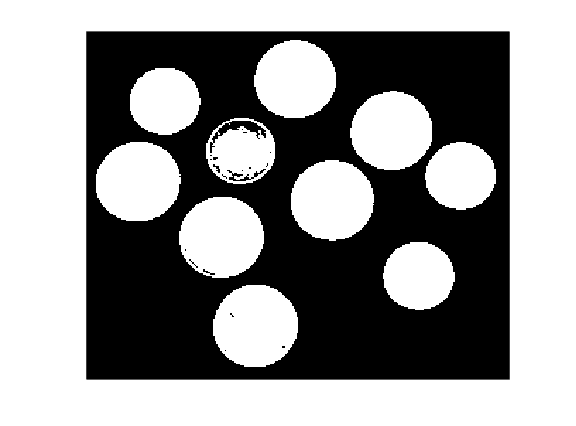

imshow(c2)

L = bwlabel(c2,8)

L =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

max(max(L))

ans = 10